importdata DataExam.xlsx;
Estatura=table2array(DataExam(:,"Estatura"));
Talla=table2array(DataExam(:,"Talla"));
Sexo=table2array(DataExam(:,"Sexo"));

%Estatura

Emean=mean(Estatura);

Emean = 166.9500

Estd=std(Estatura);

Estd = 9.3844

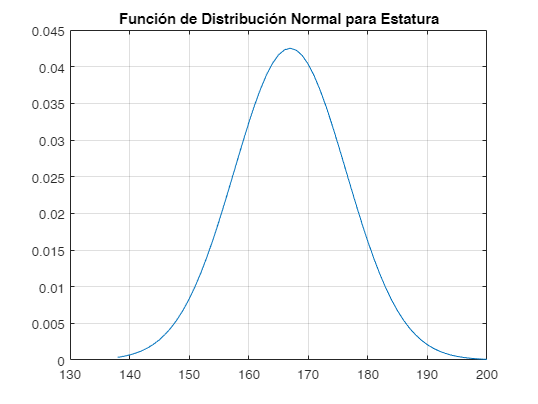

Ex=(min(Estatura)-10):1:(max(Estatura)+10);
X=fitdist(Estatura,'Normal');
Ey = normpdf(Ex,Emean,Estd);
plot(Ex,Ey)
title('Función de Distribución Normal para Estatura')
grid on
hold off

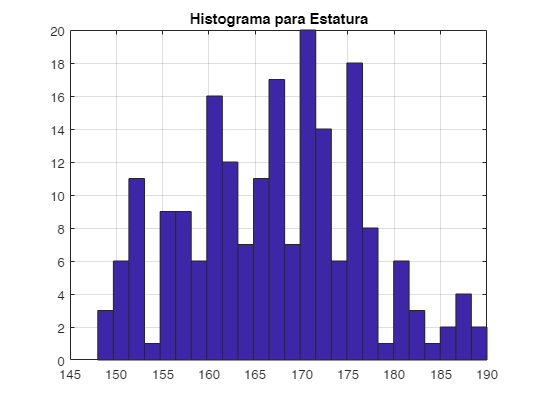

hist(Estatura,25)
title('Histograma para Estatura')
grid on
hold off


%Talla

Tmean=mean(Talla)

Tmean = 25.7475

Tstd=std(Talla)

Tstd = 1.9127

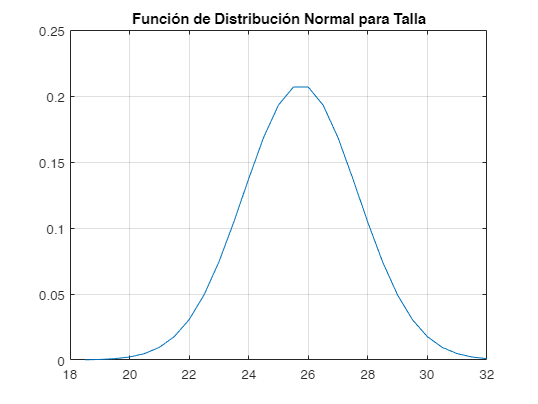

Tx=(min(Talla)-2):0.5:(max(Talla)+2);
Ty=normpdf(Tx,Tmean,Tstd);
plot(Tx,Ty)
title('Función de Distribución Normal para Talla')
grid on
hold off

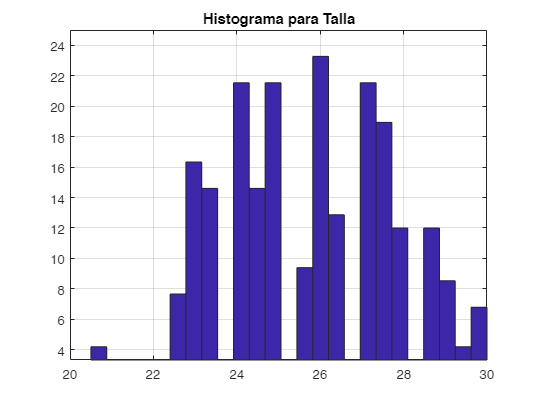

max(Ty);
hist(Talla,25)
title('Histograma para Talla')
grid on
hold off

%Probabilidades
Ep=[(Emean-Estd) (Emean+Estd)];
pE = normcdf(Ep,Emean,Estd);
PE = pE(2)-pE(1);
fprintf("La probabilidad de que la estatura de una persona al azar se encuentre dentro \nde la primera desviación estandar es %.2f %%",(PE*100))

La probabilidad de que la estatura de una persona al azar se encuentre dentro 
de la primera desviación estandar es 68.27 %


Tp=[(Tmean-Tstd) (Tmean+Tstd)];
pT = normcdf(Tp,Tmean,Tstd);
PT = pT(2)-pT(1);
fprintf("La probabilidad de que la talla de una persona al azar se encuentre dentro \nde la primera desviación estandar es %.2f %%",(PT*100))

La probabilidad de que la talla de una persona al azar se encuentre dentro 
de la primera desviación estandar es 68.27 %

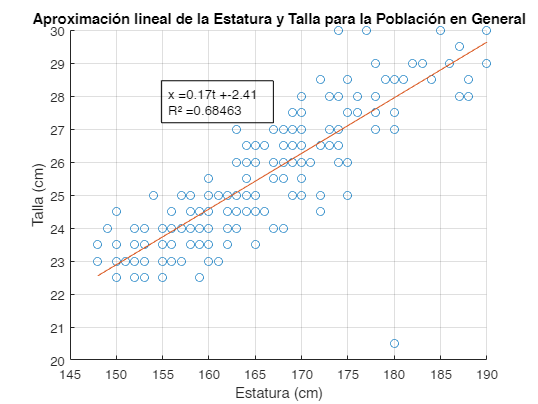


%Aproximación Lineal

MI = find(Sexo=="Masculino");
FI = find(Sexo=="Femenino");
mE = Estatura(MI);
MT = Talla(MI);
fE = Estatura(FI);
FT = Talla(FI);

%General
figure(1)
E = [ones(length(Estatura),1) Estatura];
bE = E\Talla;
ECalc = E*bE;
bE=round(bE,2);
Rsq2E = 1 - sum((Talla - ECalc).^2)/sum((Talla - mean(Talla)).^2);
scatter(Estatura,Talla)
hold on
plot(Estatura,ECalc)
xlabel('Estatura (cm)')
ylabel('Talla (cm)')
dim = [.3 .5 .3 .3];
strE = {strcat('x = ',num2str(bE(2)),'t + ',num2str(bE(1))),strcat('R² = ',num2str(Rsq2E))};
annotation('textbox',dim,'String',strE,'FitBoxToText','on');
title('Aproximación lineal de la Estatura y Talla para la Población en General')
grid on
hold off

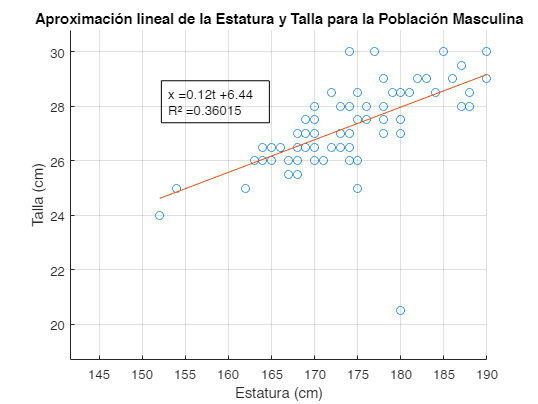


%Masculino
figure(2)
ME = [ones(length(mE),1) mE];
bME = ME\MT;
MECalc = ME*bME;
bME=round(bME,2);
Rsq2ME = 1 - sum((MT - MECalc).^2)/sum((MT - mean(MT)).^2);
scatter(mE,MT)
hold on
plot(mE,MECalc)
xlabel('Estatura (cm)')
ylabel('Talla (cm)')
dim = [.3 .5 .3 .3];
strME = {strcat('x = ',num2str(bME(2)),'t + ',num2str(bME(1))),strcat('R² = ',num2str(Rsq2ME))};
annotation('textbox',dim,'String',strME,'FitBoxToText','on');
title('Aproximación lineal de la Estatura y Talla para la Población Masculina')
grid on
hold off

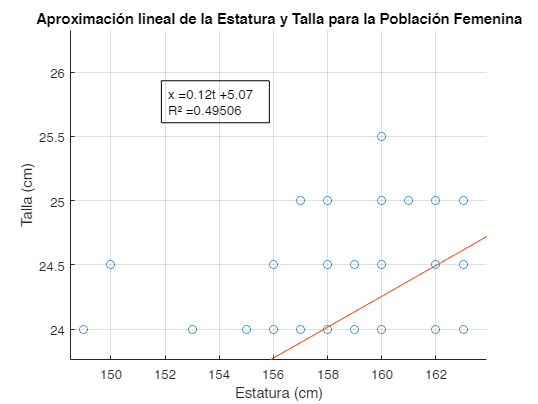


%Femenino
figure(3)
FE = [ones(length(fE),1) fE];
bFE = FE\FT;
FECalc = FE*bFE;
bFE=round(bFE,2);
Rsq2FE = 1 - sum((FT - FECalc).^2)/sum((FT - mean(FT)).^2);
scatter(fE,FT)
hold on
plot(fE,FECalc)
xlabel('Estatura (cm)')
ylabel('Talla (cm)')
dim = [.3 .5 .3 .3];
strFE = {strcat('x = ',num2str(bFE(2)),'t + ',num2str(bFE(1))),strcat('R² = ',num2str(Rsq2FE))};
annotation('textbox',dim,'String',strFE,'FitBoxToText','on');
title('Aproximación lineal de la Estatura y Talla para la Población Femenina')
grid on